# Control de posición del variador-motor con PID

# 1. Estado del arte - PID

Un controlador o regulador PID es un dispositivo que permite controlar un sistema en lazo cerrado para que alcance el estado de salida deseado. El controlador PID está compuesto de tres elementos que proporcionan una acción Proporcional, Integral y Derivativa. Estas tres acciones son las que dan nombre al controlador PID.

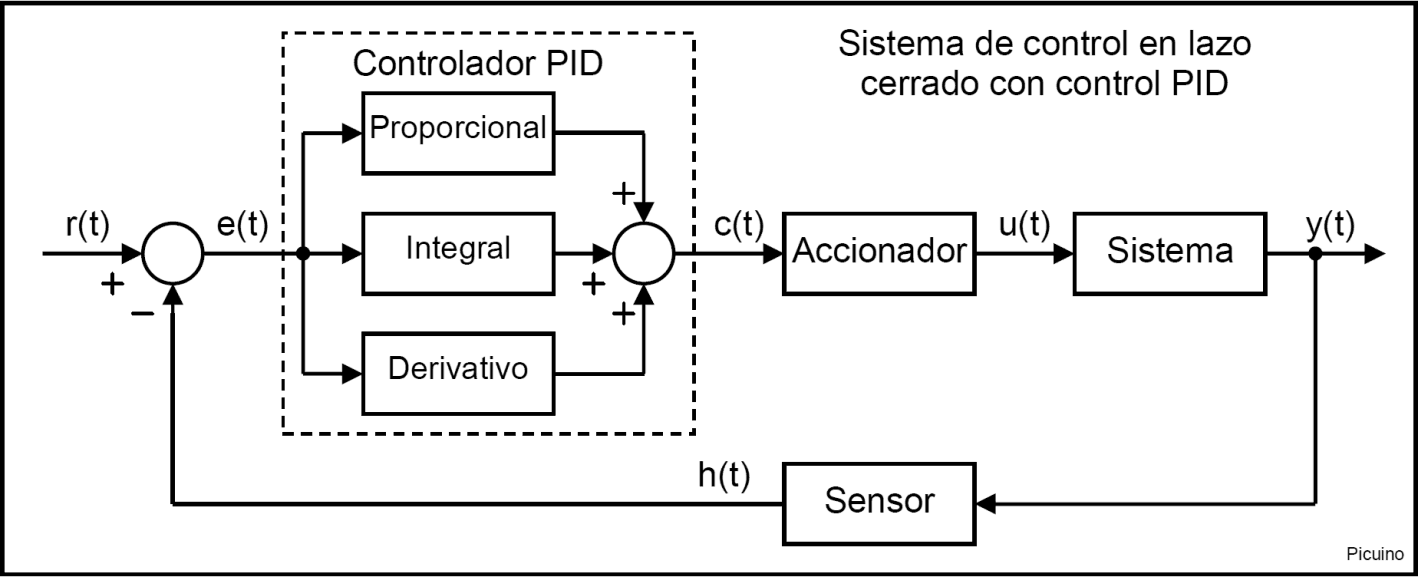

## **1.1 Acción de control Proporcional**

Como su nombre indica, esta acción de control es proporcional a la señal de error e(t). Internamente la acción proporcional multiplica la señal de error por una constante **Kp** que determina la cantidad de acción proporcional que tendrá el controlador.

Esta acción de control intenta minimizar el error del sistema. Cuando el error es grande, la acción de control es grande y tiende a minimizar este error.

Aumentar la acción proporcional **Kp** tiene los siguientes efectos:

- Aumenta la velocidad de respuesta del sistema.

- Disminuye el error del sistema en régimen permanente.

- Aumenta la inestabilidad del sistema.

Los dos primeros efectos son positivos y deseables. El último efecto es negativo y hay que intentar que sea reducido. Al aumentar la acción proporcional existe un punto de equilibrio en el que se consigue suficiente rapidez de respuesta del sistema y reducción del error, sin que el sistema sea demasiado inestable. Aumentar la acción proporcional más allá de este punto producirá una inestabilidad indeseable. Reducir la acción proporcional, reducirá la velocidad de respuesta del sistema y aumentará su error permanente.

## **1.2 Acción de control Derivativa**

Como su nombre indica, esta acción de control es proporcional a la derivada de la señal de error e(t) multiplicada por la constante **Kd**. La derivada del error es otra forma de llamar a la "velocidad" del error. 

Aumentar la constante de control derivativa **Kd** tiene los siguientes efectos:

- Aumenta la estabilidad del sistema controlado.

- Disminuye un poco la velocidad del sistema.

- El error en régimen permanente permanecerá igual.

Esta acción de control servirá, por lo tanto, para estabilizar una respuesta que oscile demasiado.

## **1.3 Acción de control Integral**

Esta acción de control, como su nombre indica, calcula la integral de la señal de error e(t) y la multiplica por la constante **Ki**. La integral se puede ver como la suma o acumulación de la señal de error. A medida que pasa el tiempo pequeños errores se van sumando para hacer que la acción integral sea cada vez mayor. Con esto se consigue reducir el error del sistema en régimen permanente. La desventaja de utilizar la acción integral consiste en que esta añade una cierta inercia al sistema y, por lo tanto, le hace más inestable.

Aumentar la acción integral **Ki** tiene los siguientes efectos:

- Disminuye el error del sistema en régimen permanente.

- Aumenta la inestabilidad del sistema.

- Aumenta un poco la velocidad del sistema.

Esta acción de control servirá para disminuir el error en régimen permanente.

## **1.4 Reglas de Ziegler-Nichols para la sintonía de controladores PID**

Ziegler y Nichols propusieron reglas para determinar los valores de la ganancia proporcional Kp, del tiempo integral Ti y del tiempo derivativo Td, basándose en las características de respuesta transitoria de una planta dada. Tal determinación de los parámetros de los controladores PID o sintonía de controladores PID la pueden realizar los ingenieros mediante experimentos sobre la planta. (Después de la propuesta inicial de Ziegler-Nichols han aparecido numerosas reglas de sintonía de controladores PID. Estas reglas están disponibles tanto en publicaciones técnicas como de los fabricantes de estos controladores.)

Hay dos métodos denominados reglas de sintonía de Ziegler-Nichols: el primero y el segundo método. A continuación se hace una breve presentación de estos dos métodos.

### **1.4.1. Primer método**. 

En el primer método, la respuesta de la planta a una entrada escalón unitario se obtiene de manera experimental, tal como se muestra en la Figura 1. Si la planta no contiene integradores ni polos dominantes complejos conjugados, la curva de respuesta escalón unitario puede tener forma de S, como se observa en la Figura 2. Este método se puede aplicar si la respuesta muestra una curva con forma de S. Tales curvas de respuesta escalón se pueden generar experimentalmente o a partir de una simulación dinámica de la planta. La curva con forma de S se caracteriza por dos parámetros: el tiempo de retardo L y la constante de tiempo T. El tiempo de retardo y la constante de tiempo se determinan dibujando una recta tangente en el punto de inflexión de la curva con forma de S y determinando las intersecciones de esta tangente con el eje del tiempo y con la línea $C_{\left(t\right)} =K$, tal como se muestra en la tabla 1.

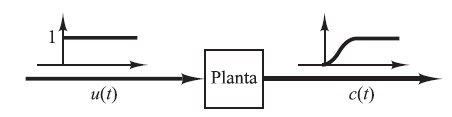

**FIGURA 1: Respuesta a un escalón unitario de una planta**

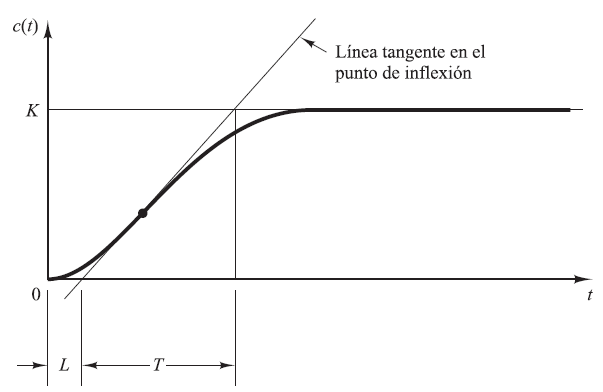

**FIGURA 2: Curva de respuesta en forma de S.**

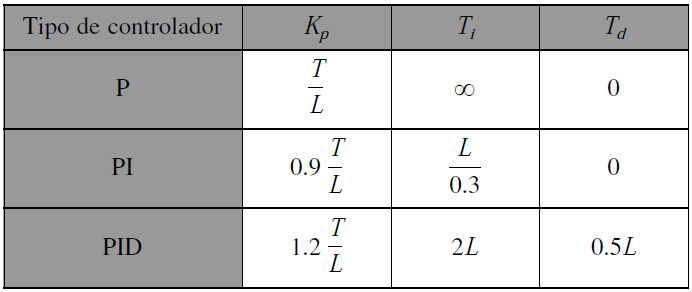

**TABLA 1: Regla de sintonía de Ziegler-Nichols basada en la respuesta escalón de la planta (primer método).**

### **1.4.2. Segundo método**.

En el segundo método, primero se fija $T_i =\infty$ y $T_d =0$. Usando sólo la acción de control proporcional Figura 3, se incrementa Kp desde 0 hasta un valor crítico Kcr, en donde la salida presente oscilaciones sostenidas. (Si la salida no presenta oscilaciones sostenidas para cualquier valor que pueda tomar Kp, entonces este método no se puede aplicar.) Así, la ganancia crítica Kcr y el periodo Pcr correspondiente se determinan experimentalmente Figura 4. Ziegler-Nichols sugirieron que se establecieran los valores de los parámetros $K_P$, $T_i$ y $T_d$ de acuerdo con la fórmula que se muestra en la Tabla 2.

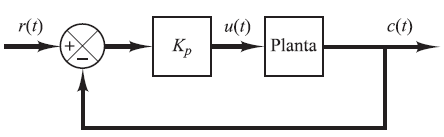

**FIGURA 3: Sistema en lazo cerrado con un controlador proporcional.**

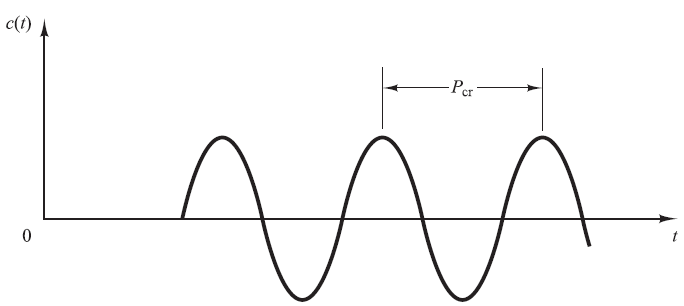

**FIGURA 4: Oscilación sostenida con periodo Pcr (Pcr se mide en seg.).**

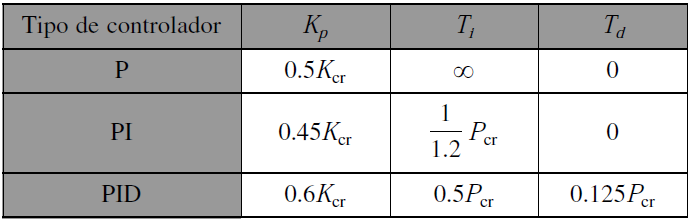

**TABLA 2: Regla de sintonía de Ziegler-Nichols basada en la ganancia crítica Kcr**

**y periodo crítico Pcr (segundo método).**

# 2. Modelo matemático de la planta y análisis

En esta parte el análisis de la planta es el mismo realizado para el realizado en la realimentación de estados

## 2.1 Función de transferencia

Entrada de la función de transferencia experimental es voltaje y la salida velocidad angular [rad/seg]. La función que se obtuvo es como sigue:


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\textrm{rad}/\textrm{seg}}{V}\right\rbrack$$


f_motor_rad=tf(26.55,[1 5.163 15.58])

f_motor_rad =
 
          26.55
  ---------------------
  s^2 + 5.163 s + 15.58
 
Continuous-time transfer function.



Se comprueba estabilidad BIBO, es decir, los polos deben tener parte real negativa:

pole(f_motor_rad)

ans =   -2.5815 + 2.9859i
  -2.5815 - 2.9859i


Queda así comprobado la estabilidad BIBO, con lo que la respuesta ante la entrada escalón debe tener respuesta en estado estacionario:

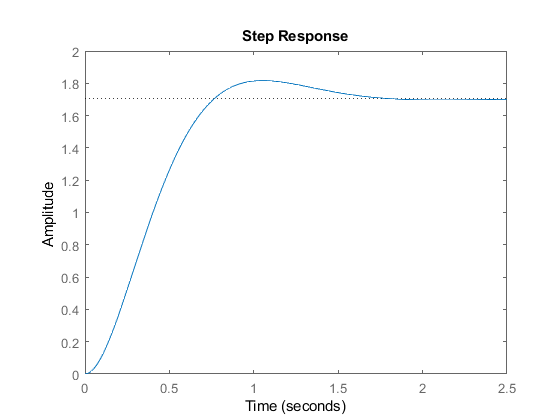

step(f_motor_rad)

La función de transferencia mostrada es una que relaciona la velocidad angular y el voltaje aplicado a la entrada del variador de frecuencia, sin embargo, para realizar un control de posición va a ser necesario obtener una función de transferencia que relaciona la posición y el voltaje de entrada. Para este propósito se parte de que la velocidad angular es la primera derivada de la posición angular:


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{\Theta^˙ \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\textrm{rad}/\textrm{seg}}{V}\right\rbrack$$


Aplicando el teorema de diferenciación real de la transformada de Laplace se obtiene:


$$\Theta^˙ \left(s\right)=s\Theta \left(s\right)-\theta \left(0\right)$$


Se va a considerar que las condición inicial de posición es cero, es decir, el proceso inicia con un ángulo de cero radianes:


$$\Theta^˙ \left(s\right)=s\Theta \left(s\right)$$


s=tf('s');  
pos_mot_rad=f_motor_rad/s

pos_mot_rad =
 
            26.55
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



De igual manera que antes, se comprueba la estabilidad BIBO:

pole(pos_mot_rad)

ans =    0.0000 + 0.0000i
  -2.5815 + 2.9859i
  -2.5815 - 2.9859i


En este caso no se comprueba estabilidad BIBO, por lo que ante una entrada escalón no se alcanzara el régimen permanente:

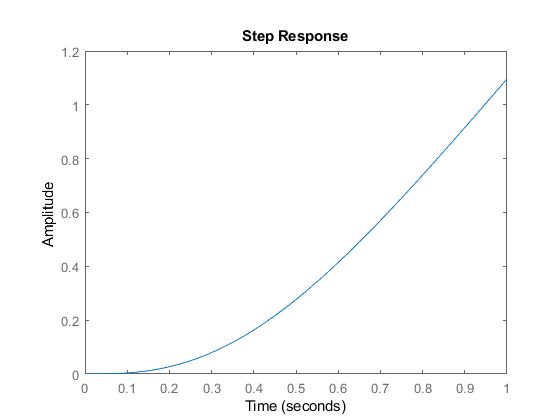

step(pos_mot_rad,1)

Se comprueba lo anteriormente dicho, sin embargo, este se trata de un sistema de tipo 1, por lo que se puede revisar el comportamiento en lazo cerrado con realimentación unitaria, donde podría estabilizarse y no tener error en estado estacionario:

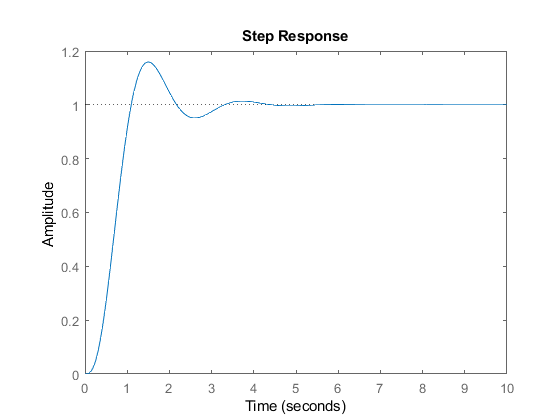

step(feedback(pos_mot_rad,1),10)

stepinfo(feedback(pos_mot_rad,1))

ans = struct with fields:
        RiseTime: 0.6615
    SettlingTime: 3.0580
     SettlingMin: 0.9144
     SettlingMax: 1.1592
       Overshoot: 15.9186
      Undershoot: 0
            Peak: 1.1592
        PeakTime: 1.5056


Lo último dicho se comprueba, además, a simple vista se puede suponer que no existe error en estado estacionario y según la respuesta del sistema podemos observar que posee una respuesta subamortiguada. Utilizando MATLAB se comprueba completamente:

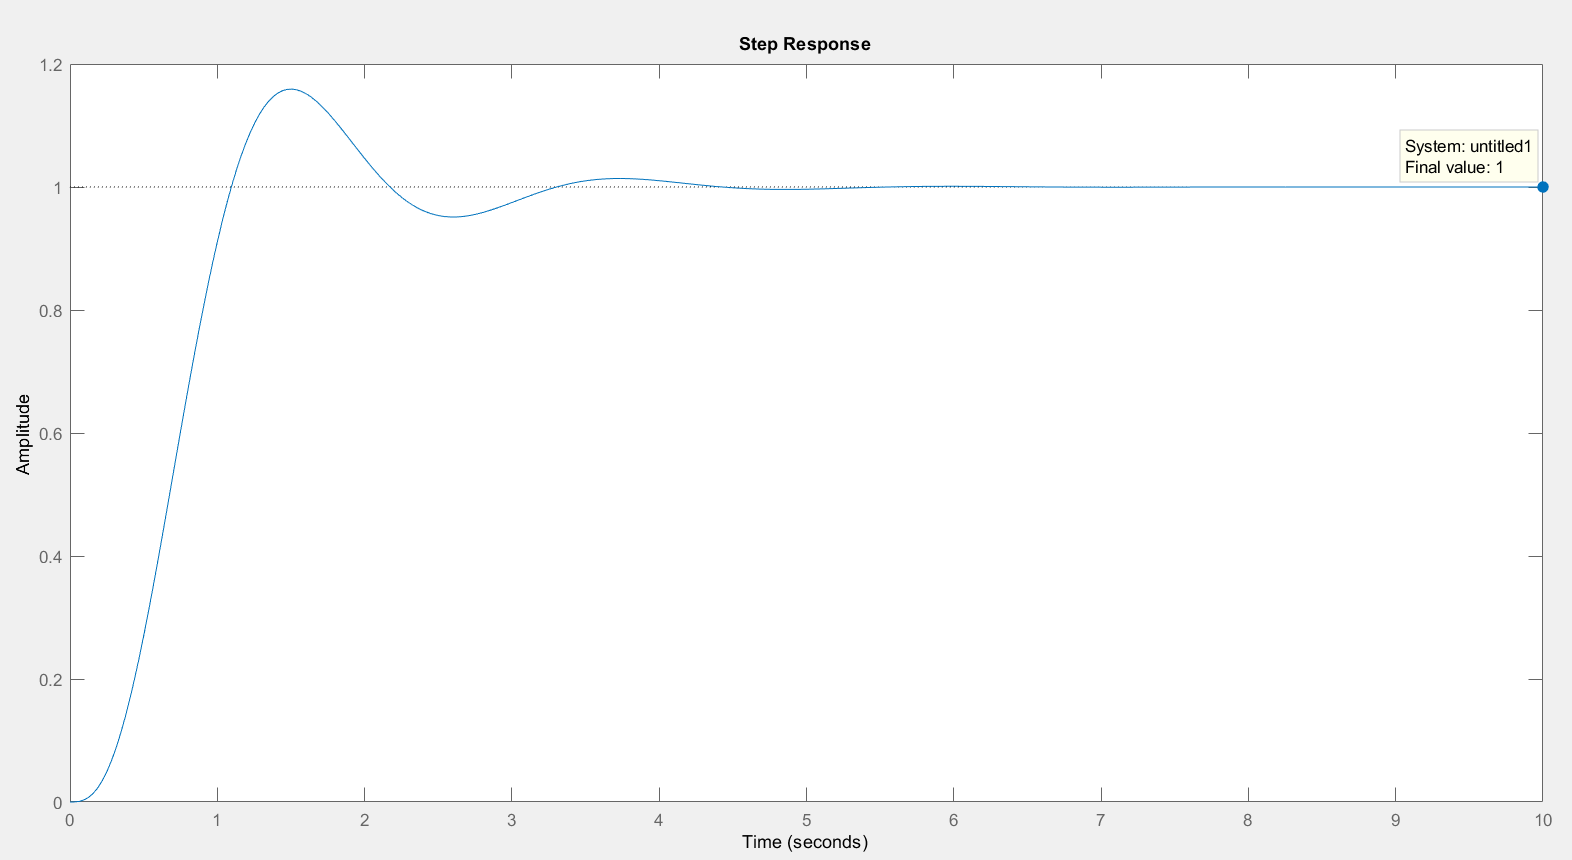

Esto nos dice que sobre esta planta se podría aplicar, más adelante, realimentación de estados con seguimiento robusto sin necesidad de agregar un integrador extra (servosistema tipo 1 con integrador en la planta)[1][2].

Hasta ahora se ha mostrado funciones de transferencia con unidades en radianes y la función que relaciona la posición, relaciona la posición angular. Pero, para los fines de la unidad de selección, es más útil tener una función de transferencia que relaciona la posición lineal, y que esta se encuentre en unidades que resulten fáciles de manejar, para esto último las unidades más sencillas de manejar son los centímetros.

Para poder relacionar la posición lineal de la cinta transportadora que se encuentra sobre eje del motor, se va a tener que suponer que no existen retardos de transporte (despreciables) sobre toda la cinta transportadora (suponer que esta es inextensible) y que la velocidad lineal del eje del motor es la misma velocidad que tendrá la cinta. Con estas suposiciones podemos decir que la longitud de arco del eje del motor y el desplazamiento de la cinta transportadora son idénticos.

Sabiendo que la longitud de arco es igual a:


$$L=r\;\theta$$


Se debe determinar el radio del eje del motor que está sujeto a la cinta transportadora, realizando mediciones simples se puede aproximar el radio a:


$$r=1\ldotp 8382\;\left\lbrack \textrm{cm}\right\rbrack$$


Por lo tanto, aplicando la ecuación de la longitud de arco sobre la función de transferencia:


$$\frac{L\left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^3 +5\ldotp 163*s^2 +15\ldotp 58*s}*1\ldotp 8382\left\lbrack \frac{\textrm{cm}}{V}\right\rbrack$$


pos_mot=pos_mot_rad*1.8382

pos_mot =
 
            48.8
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



Como tal, se está aplicando un escalamiento adecuándose la función de transferencia mediante la ecuación lineal de longitud de arco y con las unidades que queremos manejar (centímetros), por lo cual las características dinámicas no se ven alteradas más allá de la ganancia de la función de transferencia.

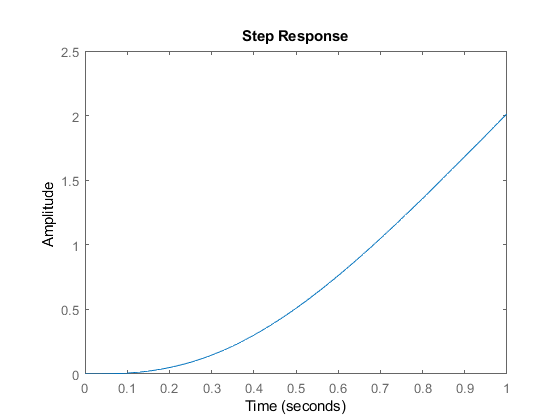

step(pos_mot,1)

# 3. Diseño del controlador

## 3.1 Análisis en tiempo continuo

El sistema (MOTOR AC + VFD) solo gira de manera horaria y no asi de manera antihoraria esto debido a las conexiones que la unidad posee entonces lo que debemos buscar en la respuesta es anular el sobrepico (Mp=0) y despues hacer que la respuesta sea rapida sin presentar dicho sobrepaso entonces para el diseño del controlador buscaremos que el sistema tenga un error en estado estacionario casi cero y Mp=0 con estos parametros es que se busara los parametros del controlador que se vaya a diseñar.

El diseño del controlador se baso en forma experimental con la aplicación **PID Tuner de MATLAB.**

Haciendo un analisis podemos concluir que la planta puede precisar un controlador **PD **o un controlador **P **ya que al tratarse de un sistema de posición este posee un integrador por lo cual se descarto el diseño del controlador **PID** (constante integral **Ki**). Con este analisis hecho podemos ingresar al PID Tuner y escoger directamente el controlador que posiblemente ayude en el rendimiento de nuestra planta en este caso se probaran dos casos un controlador **P** y un controlador **PD**

### **3.1.1. CASO 1 "CONTROLADOR PD (Proporcional Derivativo)"**

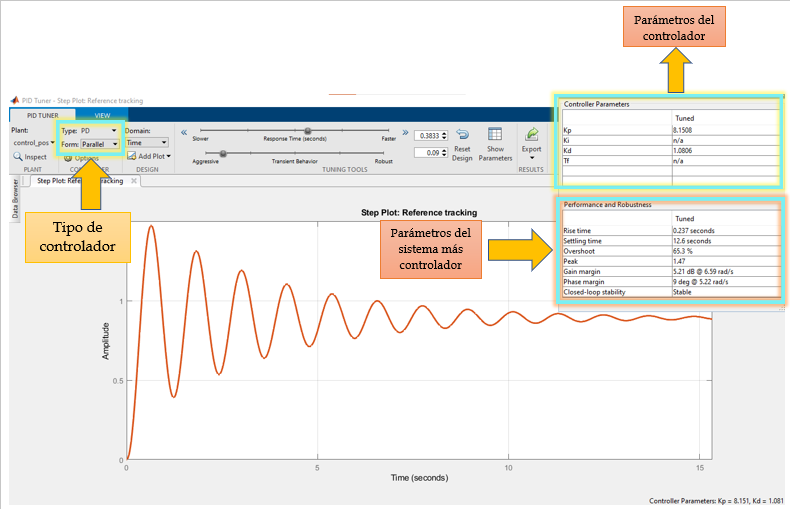

En este caso para el controlador PD se pudo observar que el sistema siempre presenta un sobrepico y oscilaciones para llegar a un estado estacionario, esto esfuerza nuestro motor por lo cual llegaria a dañarlo en algun momento. Entonces este tipo de controlador queda descartado ya que el  proceso no puede llevar a cabo esas oscilaciones para lograr estabilidad.

### **3.1.2. CASO 2 "CONTROLADOR P (Proporcional)"**

Una vez vez descartado los controlador **PID **y** PD **lo ultimo que queda es un controlador proporcional para esto lo que se hizo es variar el valor de Kp hasta lograr las especificaciones designadas.

Para hacer la experimentacion se uso el simulink se vario el valor de Kp hasta lograr encontrar el valor Kp que el sistema necesita.

### **3.1.3. Analisis matemático**

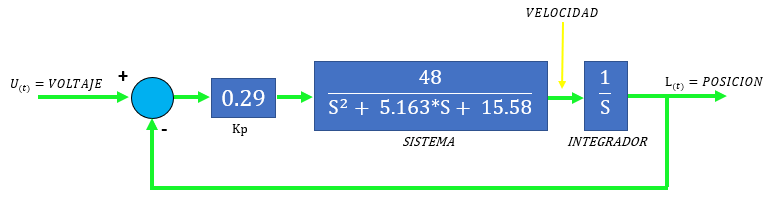

Por algebra de bloques el sistema se reducira a:


$$\textrm{Control}\_\textrm{pos}=\frac{K_P *G}{1+K_P *G}=\frac{0\ldotp 29*\frac{48}{S^3 +\ 5.163*S^2 +\ 15.58*S}}{1+0\ldotp 29*\frac{48}{S^3 +\ 5.163*S^2 +\ 15.58*S}}$$



$$\textrm{Control}\_\textrm{pos}=\frac{14\ldotp 15}{S^3 \;+\;5.163*S^2 \;+\ 15.58*S+14\ldotp 15}$$
 

### 3.1.4. Simulación

Kp=0.29; 
P_I_D = Kp;
control_pos=feedback(P_I_D*pos_mot,1)

control_pos =
 
                14.15
  ---------------------------------
  s^3 + 5.163 s^2 + 15.58 s + 14.15
 
Continuous-time transfer function.



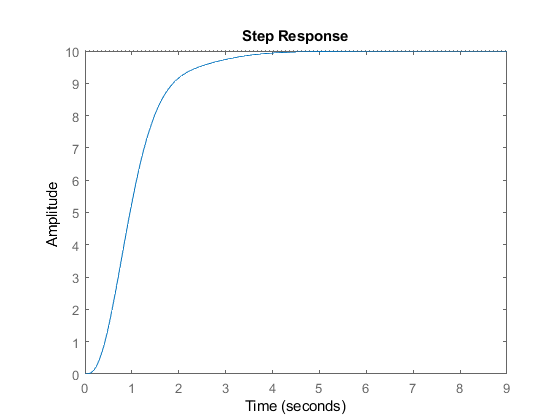

step(10*control_pos)

[num,den]=tfdata(pos_mot);
num=cell2mat(num);
den=cell2mat(den);
stepinfo(control_pos)

ans = struct with fields:
        RiseTime: 1.4548
    SettlingTime: 3.2107
     SettlingMin: 0.9027
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 10.4649


Como podemos observar una vez introducido el controlador proporcional a nuestra planta obtenemos una respuesta sobre amortiguada y con error en estado estacionario cero, con lo cual ya tenemos una respuesta adecuada y de acuerdo a nuestros parámetros establecidos. 

## 3.2 Análisis en tiempo discreto

Para poder pasar el controlador a nuestro PLC es necesario discretizar nuestro controlador para esto usaremos un tiempo de muestreo de  $T_S =27\;\textrm{ms}$.

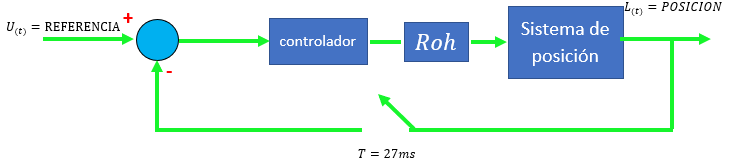

Donde:

Roh= mantenedor de irden cero 


$$\textrm{Roh}=\frac{1-e^{-\textrm{Ts}} }{s}$$



$$\textrm{Control}\_\textrm{pos}=\textrm{Sistema}+\textrm{Controlador}=$$

$$\frac{14\ldotp 15}{S^3 \;+\;5.163*S^2 \;+\ 15.58*S+14\ldotp 15}$$



$$\begin{array}{l}
G\_\textrm{final}\_\textrm{discreto}=\left(1-z^{-1} \right)Z\left(\frac{\textrm{Control}\_\textrm{pos}}{s}\right)\\
G\_\textrm{final}\_\textrm{discreto}=\left(1-z^{-1} \right)Z\left(\frac{14\ldotp 15}{\left.{S\left\lbrack S\right.}^3 \;+\;5.163*S^2 \;+\ 15.58*S+14\ldotp 15\right\rbrack }\right)\\
G\_\textrm{final}\_\textrm{discreto}=\left(1-z^{-1} \right)Z\left(\frac{14\ldotp 15}{S\left(S+1\ldotp 3598\right)\left(S^2 +3\ldotp 8032S+10\ldotp 4084\right)}\right)
\end{array}$$


aplicando la transformada z a la expresión de la derecha y reduciendo los terminos nos quedara la siguiente expresion:


$$G\_\textrm{final}\_\textrm{discreto}=\frac{4\ldotp 483*{10}^{-5} z^{-1} +1\ldotp 731*{10}^{-4} z^{-2} +4\ldotp 181*{10}^{-5} z^{-3} }{1-2\ldotp 859z^{-1} +2\ldotp 729z^{-2} -0\ldotp 8698z^{-3} }$$


### 3.2.1. Simulacion

Ts=27e-3

Ts = 0.0270

pos_mot_discreto=c2d(pos_mot,Ts,'zoh')

pos_mot_discreto =
 
  0.0001546 z^2 + 0.000597 z + 0.0001442
  --------------------------------------
    z^3 - 2.859 z^2 + 2.729 z - 0.8699
 
Sample time: 0.027 seconds
Discrete-time transfer function.



[num1,den1]=tfdata(pos_mot_discreto);
num1=cell2mat(num1)

num1 = 	1.0e+-3 *

         0    0.1546    0.5970    0.1442


den1=cell2mat(den1)

den1 =     1.0000   -2.8593    2.7292   -0.8699


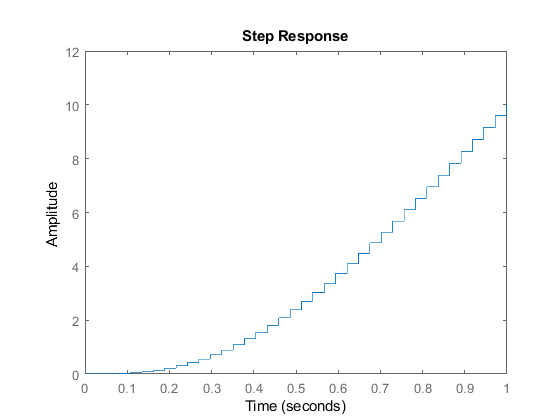

step(5*pos_mot_discreto,1)

controlador_discreto = P_I_D;
G_final_discreto=feedback(controlador_discreto*pos_mot_discreto,1)

G_final_discreto =
 
  4.483e-05 z^2 + 0.0001731 z + 4.181e-05
  ---------------------------------------
    z^3 - 2.859 z^2 + 2.729 z - 0.8698
 
Sample time: 0.027 seconds
Discrete-time transfer function.



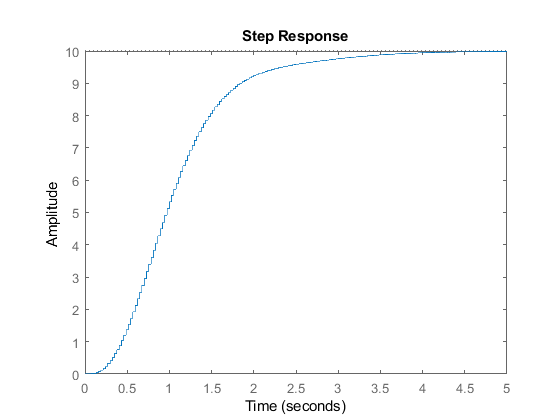

step(10*G_final_discreto)

La ecuación del controlador en tiempo discreto es:


$$\frac{m_{\left(z\right)} }{e_{\left(z\right)} }=\ 0.29$$


Llevando a una ecuación en recurrencia tenemos:


$$M_{\left(K\right)} ={0.29*E}_{\left(K\right)}$$


## 3.3 **Pruebas en SIMULINK**

Para la simulacion en simulink lo que se hizo es primero armar el diagrama de bloques completo del sistema en general en este caso los componentes que tomamos en cuenta fueron:

- Gnanancia (Controlador **P**)

- Planta (Pos_mot)

- Saturacion

- Zona muerta

- Sumadores

- Entrada (Escalon unitario)

- Osciloscopio

Con estos componenetes se armo el diagrama de bloques para poder hacer la simulacion respectiva.

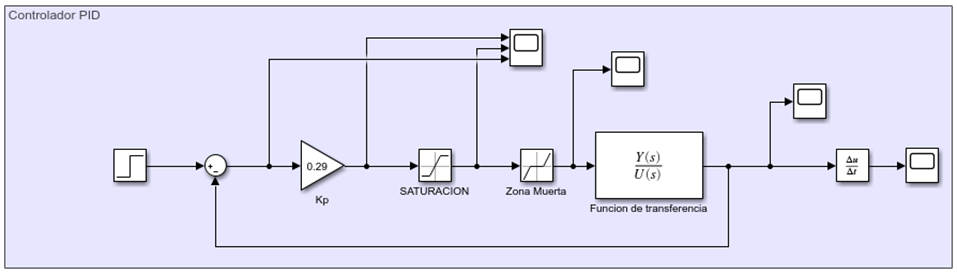

**Diagrama de bloques planta mas controlador a lazo cerrado**

La respuestas que obtuvimos fueron las iguientes:

- Señal de control 

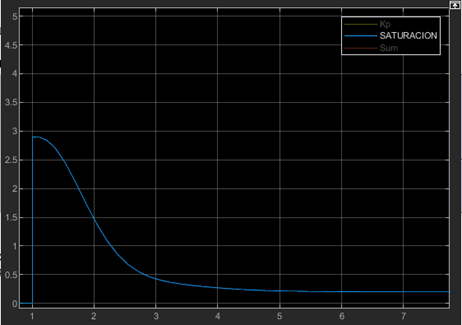

**SEÑAL DE CONTROL      **

- Respuesta del sistema (variable posición)

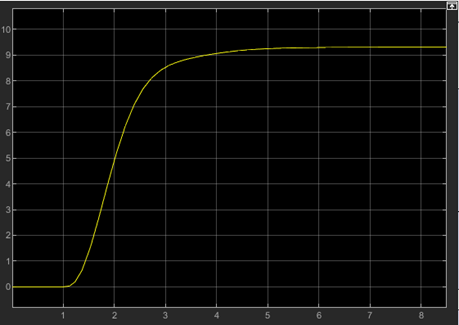

**RESPUESTA DEL SISTEMA DE POSICION  **

- Respuesta del sistema (variable velocidad)

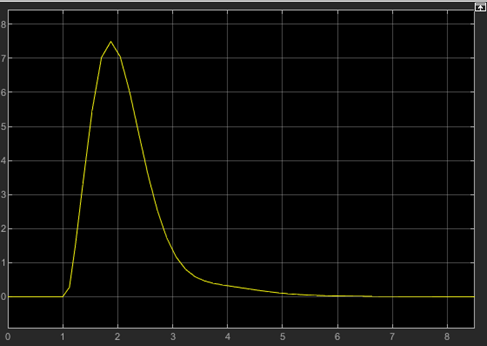

**Respuesta del sistema en función de la velocidad**

# **4. Contrastar datos con la simulación**

En este caso se implementó el controlador en tiempo discreto en el PLC S7-200, entonces, se pudo obtener, mediante el uso de la instrumentación específica (osciloscopio), la señal de control proveniente de la salida analógica del PLC (DAC) y se puede comparar con la simulación de la señal de control obtenida con las simulaciones y el simulink:

Lo que haremos para la vaidacion del modelo es lo siguiente:

1. Exportar los datos tomados 

            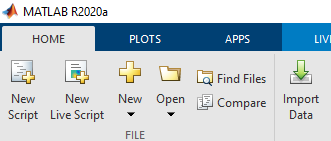

 Primero vamos a la pestaña home despues seleccionamos el icono **Import Data **una vez seguido estos pasos lo que prosigue es seleccionar el archivo donde se guardo los datos y posteriormente importar los datos del excel.

2. Tratamiento de los datos

plot(dataPID)

como podemos observar los datos necesitan ser tratados.

3. Pasar los datos por un filtro digital

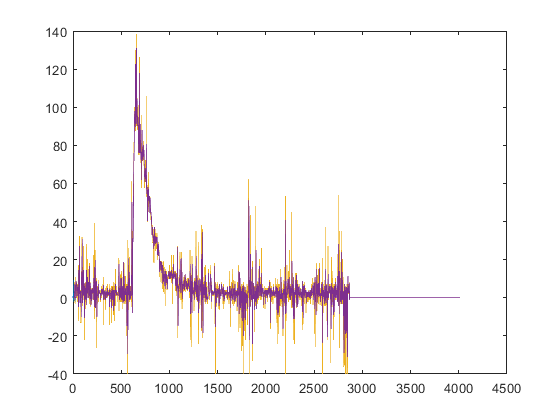

[a,b]=butter(3,0.4,'low');
fil=filter(a,b,dataPID);
plot(dataPID)
hold on
plot(fil)
hold off

4. Movemos la grafica en el eje X y lo llevamos al origen

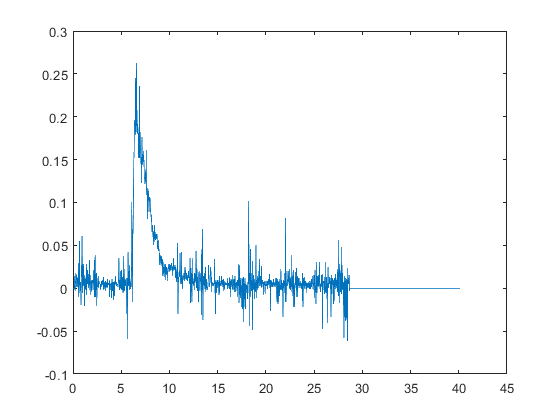

t2(1)=0;
for i=2:length(dataPID)
    t2(i)=t2(i-1)+1e-2;
end
dataPID2=fil*(5e-2)/25;
plot(t2,dataPID2)

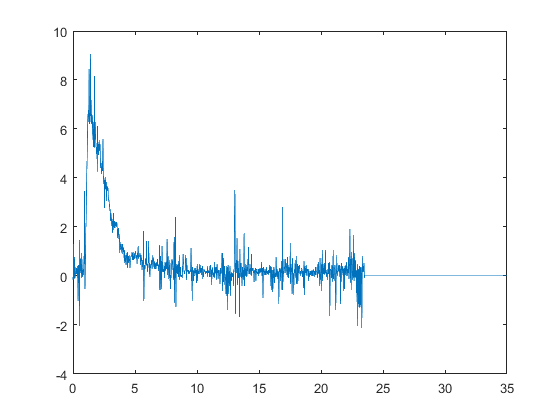

dataPID3=dataPID2*1.8382*pi*1.1962e3/200;
ta=find(t2>=5.16);
tb=ta(1);
dataPID4=dataPID3(tb:length(t2));
t3=0;
for i=2:length(dataPID4)
    t3(i)=t2(i-1)+1e-2;
end
plot(t3,dataPID4)

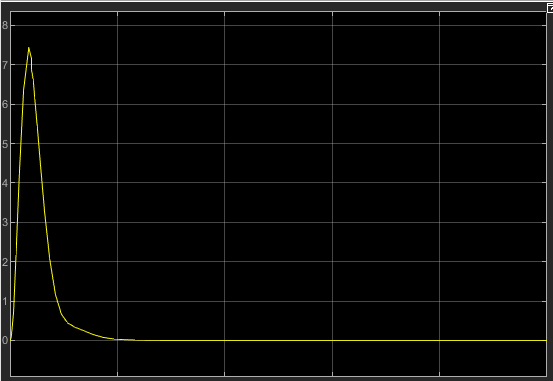

**Respuesta de la velocidad del sistema de posición**

# **5. Referencias **

- [https://www.picuino.com/es/control-pid.html](https://www.picuino.com/es/control-pid.html)

- [2] K. Ogata, *Ingeniería de control moderna*, 5a. ed. Madrid: Pearson Educación, 2010.  